# **Digital Communications TTT4130 - Matlab Lab Sessions**

**Lab Responsible**: Johan Suarez (johan.suarez@ntnu.no)

`Prerequisites`

Up-to-date installation of `MATLAB `and `SIMULINK `including `Communications Toolbox. (NTNU students receive Campus license)`

`Instructions`

**All lab sessions are group projects. Groups will be assigned randomly and consist of 2-3 people.** 

This is a Matlab live script. The script will guide through the lab session with coding tasks accompanied by explanations and comments. The live script and the project report must be completed and delivered by **18.10.2024**

**Please download and install MATLAB/Simulink and include the Communications toolbox as add-in. **

**You are free to use any resource you think is useful. Collaboration and discussion between groups is encouraged. **

# `Project 2`

This lab session covers mainly *synchronisation *in digital communication systems.

### `Digital Communiction System Schematic`

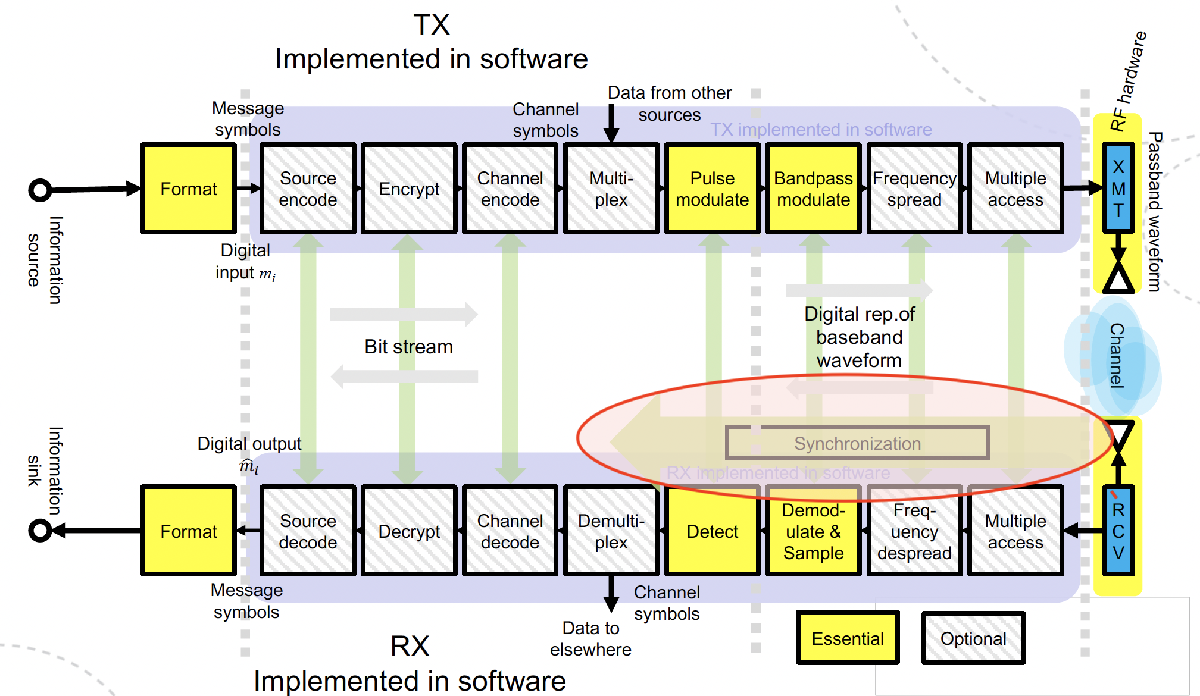

Specifically, the lab session covers the highlighted (red) parts of the schematic depicted above. 

`Course Content`

- Synchronisation in digital communication systems

- Why synchronisation is needed ... 

- Channel and hardware effects 

#### `System Configuration (known from Project 1)`

% Symbol Rate 
global symRate         % 1/s
symRate = 100

symRate = 100



SNR = Simulink.Parameter(30)       % Signal to Noise ratio, specifically Energy per bit to Noise Power density ratio (Eb/No)

SNR =   Parameter with properties:

          Value: 30
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


Select modulation scheme

modScheme = "BPSK"

modScheme = "BPSK"




% For M-ary QAM specify modulation order (TODO: assert modOrder == 2/4 for modScheme == BPSK/QPSK)

modOrder = 2

modOrder = 2

Specify Transmit Filter Parameters

alpha =0.5  % Nyquist Filter Roll-Off Factor

alpha = 0.5000



filterLenSymbols = 10;            % Filter Length in Symbols


samplesPerSymbol = 8;             % Filter Upsampling Factor


################################# NEW  ##################################

% Specify the "virtual" carrier frequency 

fCRes = Simulink.Parameter(0);




% Phase Offset
phaseOffsets = Simulink.Parameter([0;pi/8;pi/4;pi/2;pi]);

phaseOffsetSelector  = Simulink.Parameter(1);


% Toggle Synchronisation Processes

toggleFLL = Simulink.Parameter(1); 

toggleTimingRecovery = Simulink.Parameter(1); 

togglePLL = Simulink.Parameter(1); 



`Task1 : Channel Effects`

**TODO: Provide more detail regarding the phase and frequency impairment model. **

Investigate which effects a phase offset ($\Delta \phi_{\textrm{LO}}$) and a frequency offset ($\Delta f_{LO}$ ) between the Tx and Rx local oscillator (LO) have on the received signal. Use the signal model for an analytic signal upconverted to passband

##                                 
$$s_+(t) = s(t) e^{j2\pi f_{c,tx}t}$$


which is mixed to baseband by a receiver LO with frequency $f_{c,Rx}=f_{c,Tx}+\Delta f$ and relative phase offset $\Delta \phi_{\textrm{LO}}$. In this task assume that $s(t)$ are downsampled complex symbols.

% Investigate LO phase and freqeuncy offset on analytic baseband signal 

% Time of Frame including barker code (barker code is technically only needed for last exercise)
numSymbols = 100;    % Increased for better lock visualization
sps = samplesPerSymbol;            % Samples per symbol
fls = filterLenSymbols;
Ts = 1/(numSymbols*sps + 2*fls)

Ts = 0.0012

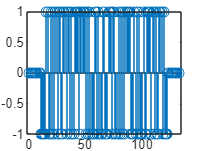

 

% Generate Tx message symbols
rng(0, "twister")

% gerenate 1000 elemtens in random sequenze of -1 and +1 symbols 
symTx = 2 * randi([0,1],numSymbols,1) - 1;

barker_code = [-1 -1 -1 -1 -1 +1 +1 -1 -1 +1 -1 +1 -1];

symTx = [zeros(fls,1); barker_code'; symTx; zeros(fls,1)];

% Plot Tx symbols
stem(1:length(symTx),real(symTx));

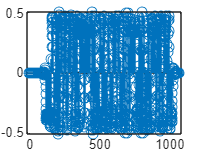


transmit_filter = comm.RaisedCosineTransmitFilter( ...
    "FilterSpanInSymbols", filterLenSymbols, ...
    "RolloffFactor", alpha, "OutputSamplesPerSymbol", sps);

symTx = transmit_filter(symTx);

stem(1:length(symTx), real(symTx));

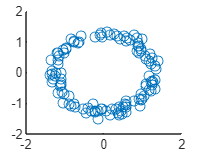


time = (0:length(symTx)-1)'*Ts;



% Generate real and imaginary parts of the noise
mu = 0;
sigma = 0.2;
symTx = awgn(symTx, 1/sigma^2, 1) + mu;

% Implement phase and frequency impairments resulting from LO offset
delta_f = 10;
%fc_Rx = -100e3;
phaseOffset = pi/12; 

% Downconvert signal to baseband
symRx = symTx .* exp(1j * 2*pi * (delta_f) * time + ones(size(time))*phaseOffset);

receiver_filter = comm.RaisedCosineReceiveFilter( ...
    "FilterSpanInSymbols",filterLenSymbols, ...
    "RolloffFactor", alpha, "InputSamplesPerSymbol", sps, "DecimationFactor",sps, "DecimationOffset", 0);

symRx = receiver_filter(symRx);
symRx = symRx(2*fls+1:end);
symRx_no_fs = receiver_filter(symTx);%received symbols with no LO offset
symRx_no_fs = symRx_no_fs(2*fls+1:end);

% Plot received symbols
%plot(symRx);
scatter(real(symRx), imag(symRx));

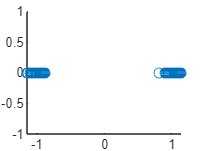

%stem(real(receiver_filter(symTx)));
scatter(real(symRx_no_fs), imag(symRx_no_fs))

`Task 2 : Synchronisation Effects`

Synchronisation in (digital) communication systems aims for removing the phase and frequency effects and impairments discussed above. The simulink model contains blocks on the receiver end of the communication link that implement the following crucial synchronisation steps:

- Coarse Frequency Correction with e.g., **Frequency-Locked Loop (FLL) **(Matlab uses corrrelation and FFT based methodss)

- Timing Offset Correction with a **Symbol Synchronizer **

- Residual Frequency Offset Correction and Phase Sychronisation with a **Phase-Locked Loop (FLL)**

**Toggle the different synchronisation steps and observe the resulting signal characterisitcs (eye diagram, constellation diagram, signal spectrum) in each case. Explain the observations and argue mathematically where you see fit. **

`Task 3 : Implementation of a Costas-Loop (data-free synchronization)`

 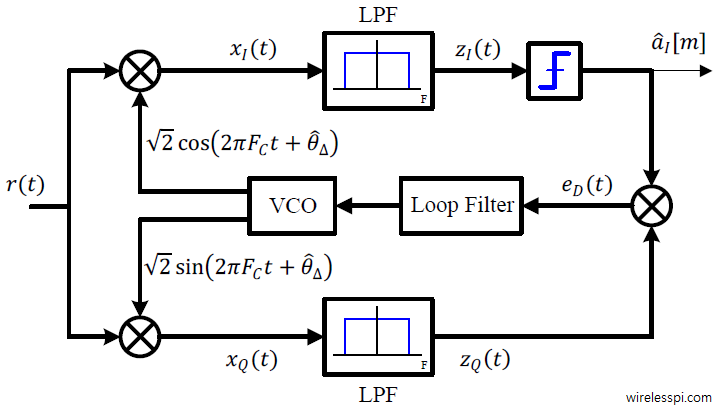

The illustration above shows the principle architecture of a *Costas Loop* for a **BPSK** receiver architecture (**NB! The illustration above treats a passband signal; our system operates on a *****complex baseband  signal***). The Costas loop is a variation of the traditional PLL that uses the IQ demodulation principles to lock onto the phase (and frequency) of a signal. 

The first step in the processing chain is the generation of the error signal $e_D$ which measures the phase difference between the reference sinusoid and the input signal. 

The *loop filter *is an integral part of the PLL. The design of the loop filter largely determines the performance characteristics of the PLL. The loop filter follows the basic structure

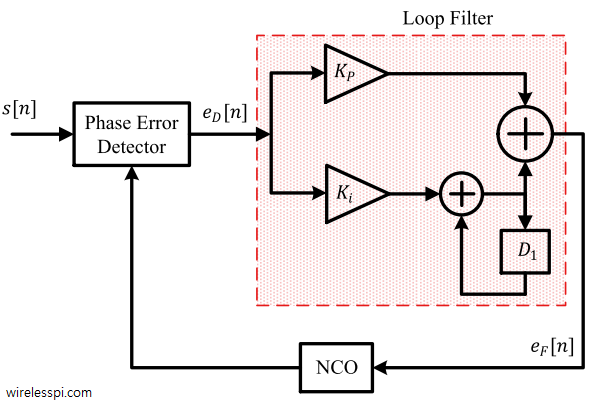

with appropriate filter coefficients $K_p
$ and $K_i$. (The *D1 *block is a one-step time-delay)

The generated and loop filtered *error signal *$e_F$ serves as input to a *Numerically Controlled Cscillator* (NCO).The NCO adjusts the phase of the generated sinusoid as

                                                             
$$\phi_{NCO}\leftarrow\phi_{NCO}+K_0e_F$$


where $K_0$ is the gain of the NCO. This essentially constitutes an integration or accumulation. 

Imlement the Costas Loop and enable your function in the simulink dashboard. Test the Costas Loop implementation first with the test signal you generated in *Task 1*. You can use the loop parameters defined in the function body. You are welcome to experiment with different parameter values; the loop parameter largely determine the the Costas loop performance, so it is interesting to observe how changes in parameters impact the outcome. 

**NB! Make sure that *****modScheme = "BPSK" *****when testing the function in the Simulink model. **

%costasLoop(...);  %

% Run the Simulink model  
% out = sim("CommSysSimulink_Project2.slx",'StopTime','inf');

% Implementation of Costas Loop
% Implementation is done in the complex regime
global T
T = 1/(symRate*samplesPerSymbol);
function symOut = costasLoop(symIn)
global symRate;
global T;
loop_bw = 0.02 * symRate; % Normalized Loop Bandwidth
zeta = 0.707;             % Damping factor (critically damped)
kpd = 1;                  % Phase Detector Gain (assuming AGC is used)
k0 = 1;                   % VCO Gain

% Calculating PI Controller Gains
wn = (4 * loop_bw * zeta) / (zeta + 1/(4*zeta));
kp = (2 * zeta * wn * T) / (kpd * k0);
ki = (wn^2 * T^2) / (kpd * k0);

% Initialize Buffers
vco_phase = 0;
loop_integral = 0;
recovered_I = zeros(size(symIn));
error_track = zeros(size(symIn));

% Processing Loop
for n = 1:length(symIn)
    % Phase Correction (Complex Mixing)
    % We rotate the signal back by the estimated VCO phase
    sample = symIn(n) * exp(-1i * vco_phase);
    
    I = real(sample);
    Q = imag(sample);
    
    % Decision-Directed Phase Error Detector (Optimized for RRC)
    % Using sign(I) makes it robust against the amplitude ripples of RRC pulses
    error = sign(I) * Q; 
    
    % Loop Filter (PI Controller)
    loop_integral = loop_integral + ki * error;
    vco_speed = kp * error + loop_integral;
    
    % Update VCO Phase for the next sample
    vco_phase = vco_phase + vco_speed;
    
    % Store outputs
    recovered_I(n) = I;
    error_track(n) = error;
end
    symOut = recovered_I;
end



`Task 4 : Data-aided synchronization`

We can make use of the *known *frame synchronisation sequence (preamble) to estimate the phase and frequency offset in the received symbols. Implement a function that estimates $\Delta\phi_{LO} $ and $\Delta f_{LO}$ from the recieved input signal. Use the estimated values to synchronize the received symbols. 

**NB! If you want to try integrating data-aided synchronisation into the Simulink model, note that the known Barker code preamble has an offset of ****10 samples ****from the start of the input sequence *****symIn*****. For application in the Simulink model, the CFO estimation needs to account for noise in the CFO estimation across frames. For this purpose the following code snippet is included in the function below**

*Can you explain this?*

% Implement a function that uses the known preamble sequence to estimate
% phase and frequency offset in the received symbol stream
% Tip: Test your function with your simulation data from task 1

% syncedData = dataAidedSync(sigDC)

% Plotting the synchronized data


% out = sim("CommSysSimulink_Project2_SOLUTION.slx",'StopTime','inf')
% dataAidedSync(testSym.')

function syncdSymOut = dataAidedSync(symIn)

Evaluating MaskInitialization for 'CommSysSimulink_Project2/AWGN Channel': 'matlab.system.MLSysBlockIconAndPortLabelsInfo.updateMLSysBlockIconAndPortLabels(gcbh)'.
Evaluating MaskInitialization for 'CommSysSimulink_Project2/BER/Error Rate Calculation': '[s] = commblkerrrate(gcb,'init'); if(PMode==1)     if(isempty(WsName))         error('commblks:ErrRa...'.
Evaluating MaskInitialization for 'CommSysSimulink_Project2/Detect Change': 'initDetectBlocks();'.
Evaluating MaskInitialization for 'CommSysSimulink_Project2/Phase// Frequency Offset': 's = commblkfreqoffset('init');'.
Evaluating MaskInitialization for 'CommSysSimulink_Project2/Raised Cosine Receive Filter/FIR Decimation': 'dtRows = dspblkGetFIRMultirateFiltersDTRowInfo(); if (FilterSource == 1) || (FilterSource == 4)     ...'.
Evaluating MaskInitialization for 'CommSysSimulink_Project2/Raised Cosine Receive Filter': '[coeff] = commblkrcfiltrx(gcbh,'init', ...     filtType, R, filtSpan, currentFiltSpan, D, N, filterG...'.
Evaluatin

Invalid setting in 'CommSysSimulink_Project2/Var2Fix' for parameter 'InputPortWidth'.

Caused by:
    Error using TTT4130_Project2 (line 254)
    Error in 'CommSysSimulink_Project2/Var2Fix'. Parameter 'InputPortWidth' containing expression "symRate*1.1" is invalid. The parameter must evaluate to real integer values


% Data aided sync using samples after symbol synchronization
% Optimized for a single 13-bit Barker sequence using Kay's Estimator

persistent cfo_est 
% Lower alpha means more smoothing. If CFO changes rapidly, increase this.
% If CFO is relatively stable, a smaller alpha (e.g., 0.1 to 0.3) helps hide the 13-bit noise.
alpha = 0.5; 

if isempty(cfo_est)
    cfo_est = 0;
end

% Single 13-bit Barker sequence
preamble = [-1 -1 -1 -1 -1 +1 +1 -1 -1 +1 -1 +1 -1].';
L = length(preamble);

% --- 1. PREAMBLE ALIGNMENT & EXTRACTION ---
% Ensure we account for the 10-sample offset explicitly to align arrays perfectly.
if coder.target('MATLAB')
    offset = 0;
else
    offset = 10; 
end

% Protect against array bounds issues in Simulink
if length(symIn) <= offset + L
    syncdSymOut = symIn;
    return;
end

% Extract EXACTLY L samples perfectly aligned with the preamble
r_preamb = symIn(offset + 1 : offset + L);

% Remove the BPSK modulation
z = r_preamb .* conj(preamble);

% --- 2. IMPROVED CFO ESTIMATION (Kay's Estimator) ---
% Delay and multiply by 1 sample
diff_z = z(2:end) .* conj(z(1:end-1));
angles = angle(diff_z);

% Compute optimal parabolic weights for L samples
k = (1:L-1).';
weights = (1.5 * L / (L^2 - 1)) .* (1 - ((2*k - L) ./ L).^2);

% Instantaneous CFO estimate (radians/sample)
dw = sum(weights .* angles);

% --- 3. APPLY SMOOTHING ---
% Update the persistent variable
cfo_est = dw * alpha + (1 - alpha) * cfo_est;

% --- 4. PHASE ESTIMATION ---
% Remove the estimated frequency offset from the preamble to find the static phase offset.
% IMPORTANT: Use the smoothed cfo_est here, not the instantaneous dw.
t_preamb = (0:L-1).';
z_corrected = z .* exp(-1j * cfo_est * t_preamb);
phi0 = angle(sum(z_corrected));

% --- 5. DATA CORRECTION ---
% Define indices for the data portion strictly AFTER the preamble
idx_data = (offset + L + 1 : length(symIn)).';

% Time vector for the data symbols relative to the start of the preamble
t_data = (L : length(symIn) - offset - 1).'; 

% Extract and rotate the data
data_in = symIn(idx_data);
syncdSymOut = data_in .* exp(-1j * (cfo_est * t_data + phi0));


end

out = sim("CommSysSimulink_Project2.slx",'StopTime','inf')
